% reads the image 
i = imread('badContrast.png')

i = 200×300 uint8 matrix
   10    0    5    8   11   18   21    1    2    8   11    0    6    2    2    3    3    2   16   23   14    7   11    6    8   10   16   12    6    1   12   14   16    3   13    1   16   14   37   11   11   18    0   23   29   47   38   39   40   51
    5   11    6    6    0   15   24    6    3    9    7    0    5    1    1    1   12    3    3   14   17   14    3    5   12   10    1    5    2   13   12    1    6   14   12   49   18   17    0   15    8   50   50   42   66   30   20   28   29   25
    7   15    1    3    6    7   21    9    2    9    7    8    6    6    1    1    2   10    3    2   14   22   17    2    3   10   12    2    1    1    2    1    1   12   14   15    9   14   24   24   41    9   37    0    3   27   10   13    5    9
    5    4    6    2    2    1    4    5    6    0    7    8    1    2    2    3    9   10   14   10    2   10   16   19    1   10   14   12    2    6    1    2    3    3   19   12   19   13   46   24   15    5   41   37  

% performs histogram equalization on the image 
ih = histeq(i);

% computes histograms for the original and equalized image 
original_hist = imhist(i)

original_hist =         4530
        2904
        2924
        2664
        3911
        3188
        3102
        4700
        3922
        3416


equalized_hist = imhist(ih)

equalized_hist =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


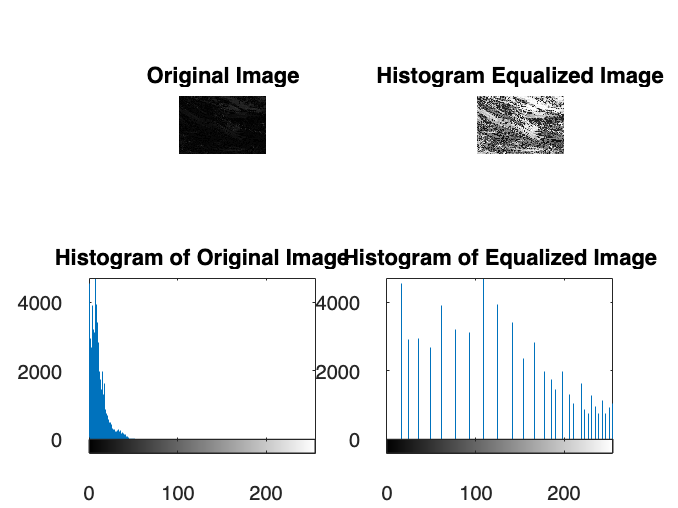


% displays original and equalized images with titles 
subplot(2,2,1), imshow(i), title('Original Image');
subplot(2,2,2), imshow(ih), title('Histogram Equalized Image');

% plots respective histograms with titles 
subplot(2,2,3), imhist(i), title('Histogram of Original Image');
subplot(2,2,4), imhist(ih), title('Histogram of Equalized Image');

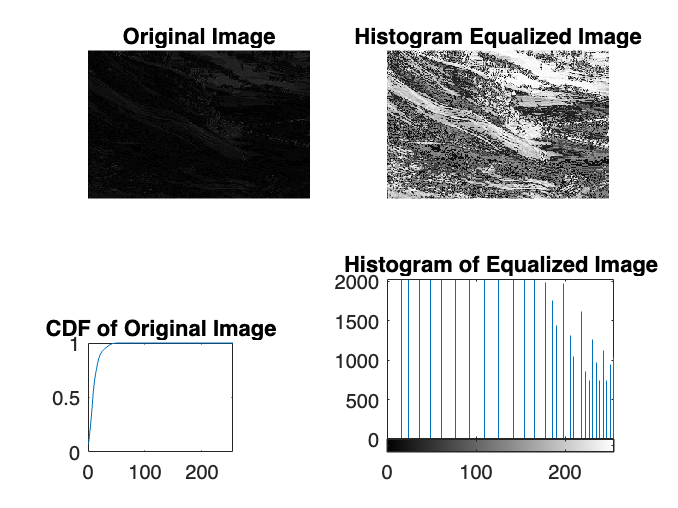


% computes and plots cdf functions 
cdf_original = cumsum(original_hist) / numel(i);
cdf_equalized = cumsum(equalized_hist) / numel(ih);

subplot(3, 3, 7), plot(cdf_original), title('CDF of Original Image'), xlim([0 255]);

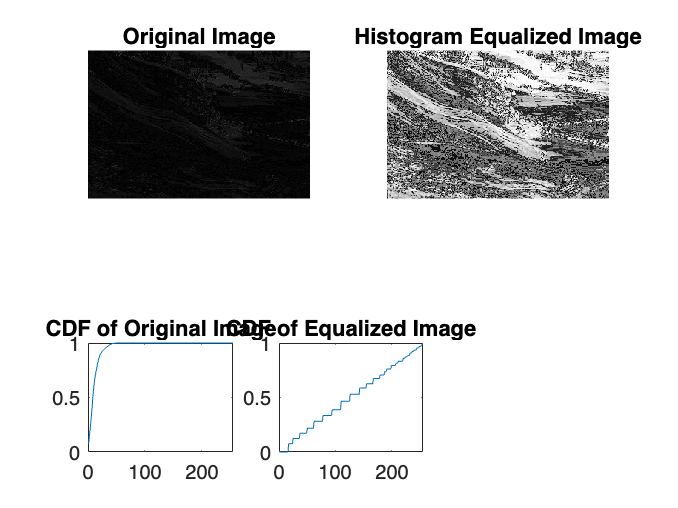

subplot(3, 3, 8), plot(cdf_equalized), title('CDF of Equalized Image'), xlim([0 255]);